## Fourier walkthrough with visualization

This live script walks you through the steps of discrete Fourier transform (DFT) and illustrates some of the principles that help or hinder the application of DFT in EEG analysis, inlcuding practical application

The goal of FFT is to take time domain data (EEG over time) and give you a frequency spectrum (Frequency domain data), i.e. a plot where frequency is on the x and the power or magnitude at each frequency is on the y-axis. 

% First, load the example data
load('bop_107.fl40h1.E1.app1.mat') % loads our example data set (129 sensors, 2551 points, 41 trials)
load taxis.mat
size(outmat)

ans =          129        2551          41


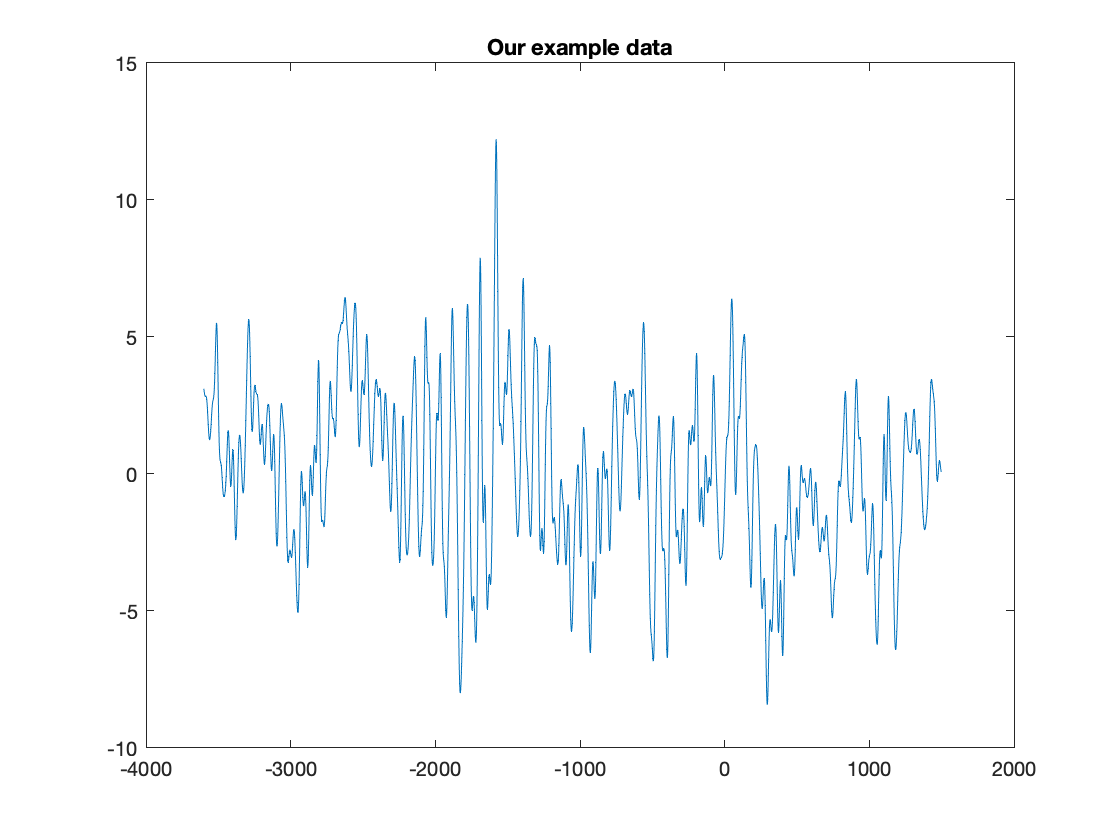

SampRate = 500; 

data = squeeze(outmat(68,:, 40))'; % this picks the 68th channel and the 40th trial (out of 41).
% squeeze gets rid of third dimension tha matlab wants to keep around, even
% thoug we only have one column vector of data now
figure, plot(taxis, data), title ('Our example data')

Question: why is it interesting to pick a trial from late in the experiment? 

Now, do a barebone DFT (FFT)

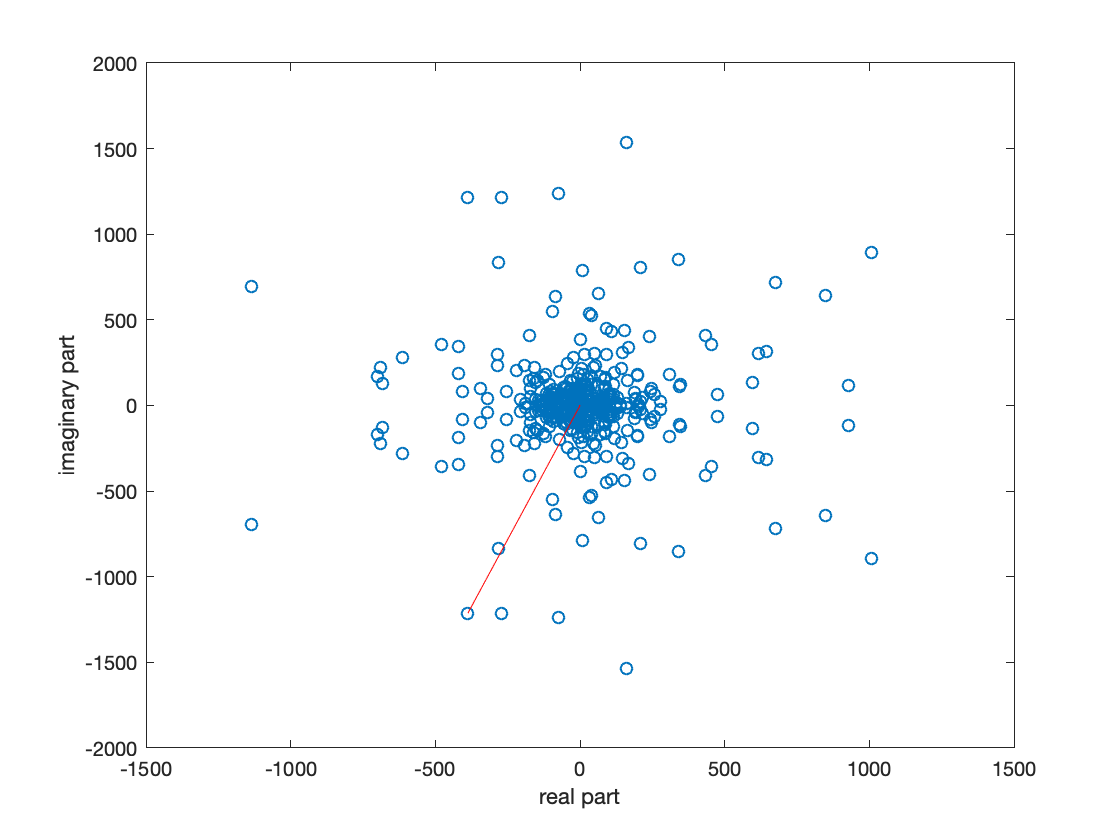

    NFFT = length(data); 

    fftMat = fft(data, NFFT);  % in matlab FFT always acros rows within columns
    
    plot(fftMat, 'o'), xlabel ('real part'), ylabel('imaginary part')
    hold on
    plot([0 fftMat(7)], 'r') % this is one frequency

    
    disp('what is the nature of the output of FFT ?')

what is the nature of the output of FFT ?


    whos 

  Name                    Size                     Bytes  Class     Attributes

  A                       1x6                         48  double              
  Ah                      1x6                         48  double              
  B                       1x6                         48  double              
  Bh                      1x6                         48  double              
  NFFT                    1x1                          8  double              
  Phase                2551x1                      20408  double              
  RawMag               2551x1                      20408  double              
  SampRate                1x1                          8  double              
  ans                     1x3                         24  double              
  cutoff                  1x1                          8  double              
  data                 2551x1                      20408  double              
  fftMat               2551x1                      

We see that the out put is "complex" so there are two numbers per number in the output, resulting in a 2-D plot. 

Also, the size of the output (fftMat) is the same as the input (2551 points) ... 

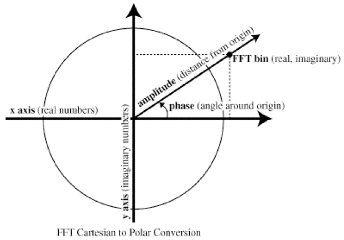

    RawMag = abs(fftMat); 
    Phase = angle(fftMat);

Raw magnitude at each frequency is the modulus (sqrt if the sum of the squares) of the two parts (real and imag). So, the length of the arrow spanned by the real and imag part in the plot above. 

Phase is the angle between real and imaginary (see above) 

Let's plot the result, focusing on power/magnitude

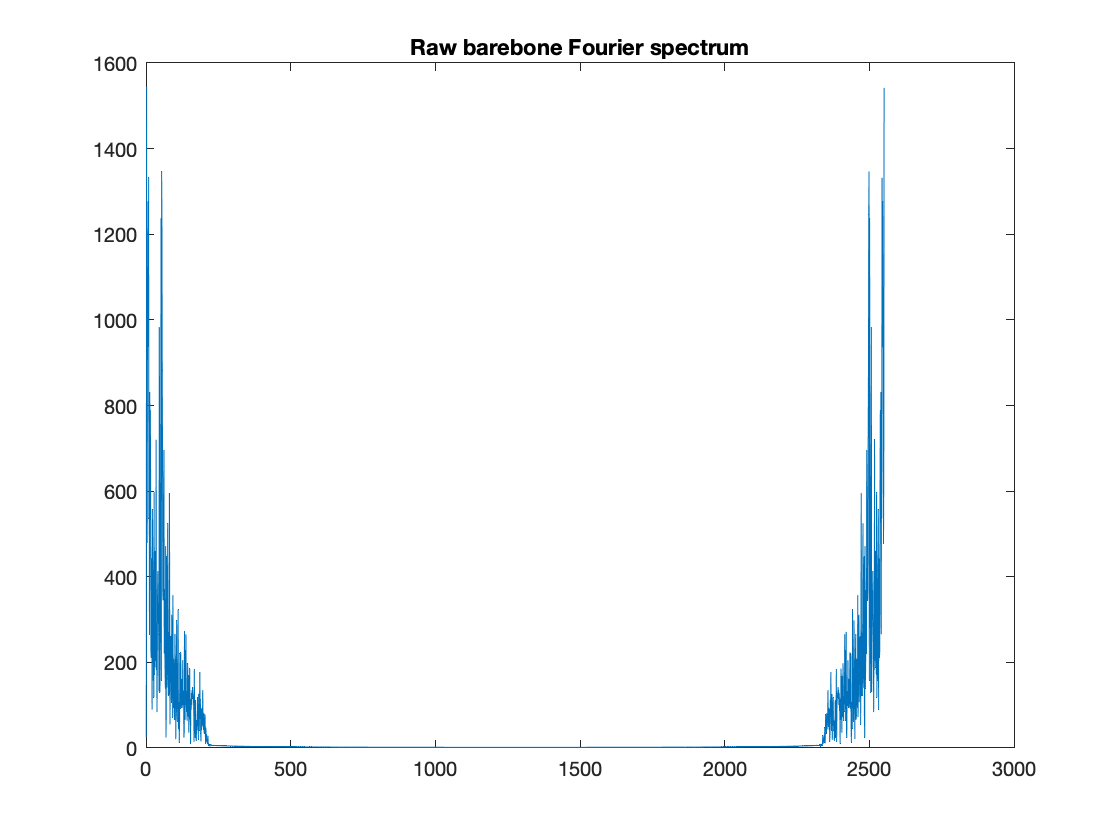

    figure, plot(RawMag), title('Raw barebone Fourier spectrum')

Note how this spectrum is symmetrical. This is because of this: 

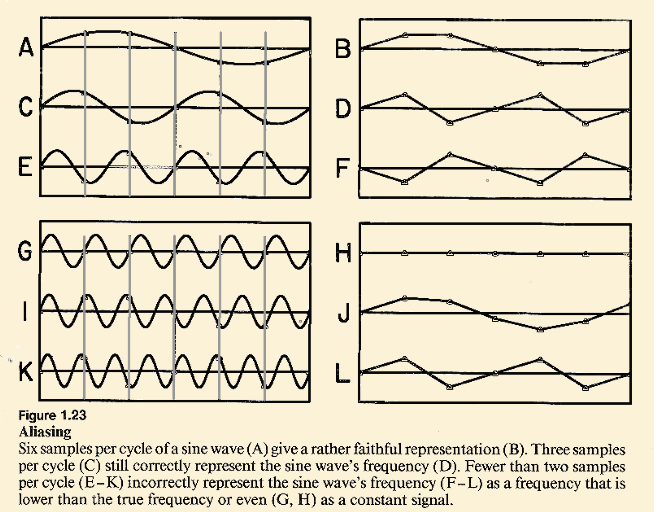

This is called the Nyquist sampling theorem. If you sample a signal digitally, any frequencies greater than half the sampling rate are meaningless repetitions of the actual ones below half the sampling rate. half the sampling rate = Nyquist frequency. 

if we apply the logic from the slides of Day 1, namely that the frequency resolution (the steps between x-ticks or bins) is 1000/length of the signal, it follows that the frequency steps here are 1000/(2551.*2) = 0.1960. Thus, 

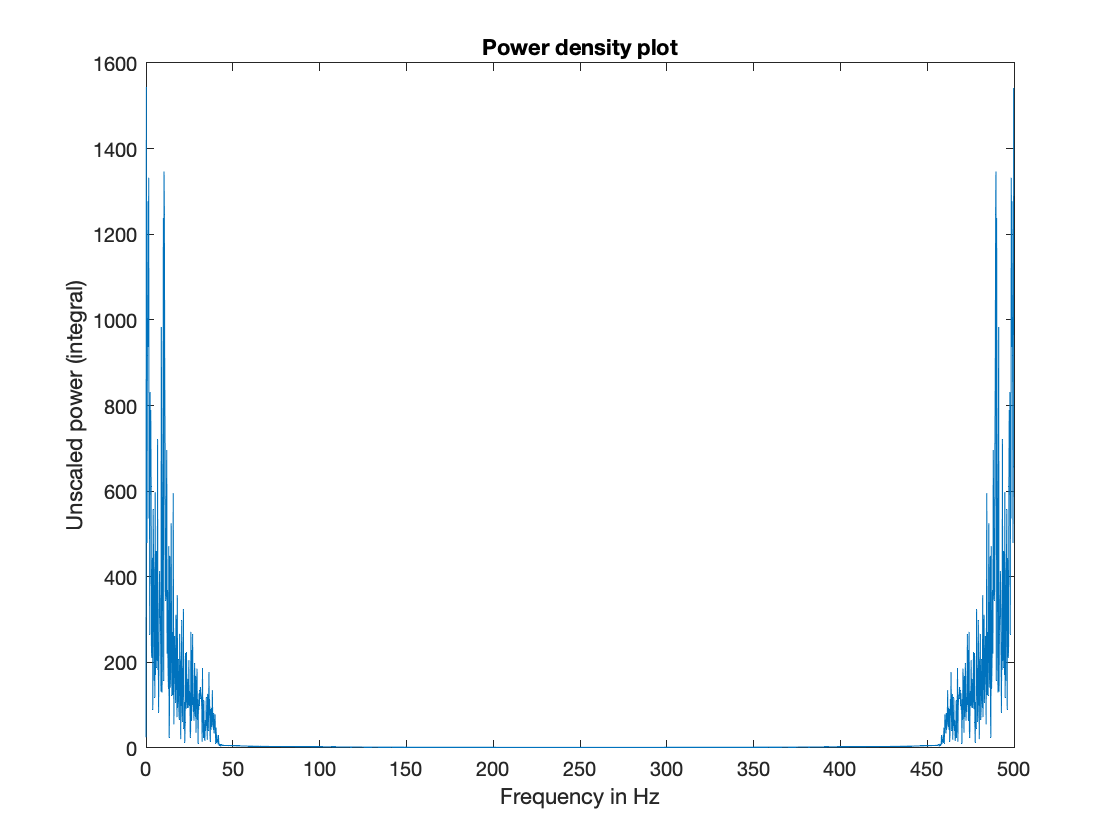

freq_axis  = 0:1000/(length(data).*2):SampRate-1000/(length(data).*2); % sample rate is 500 Hz, so each sample point has 2 ms	
figure, plot(freq_axis, RawMag), xlabel('Frequency in Hz'), ylabel('Unscaled power (integral)'), title('Power density plot')

Because of the Nyquist theorem, we may really only interpret the spectrum up onto half of the sampling rate, here in this example up to 250 Hz, the rest of the spectrum (above 250 Hz) is not valid. Below, we take this into account as we calculate the power. But first, power is overall greater when the signal is longer. This is bad when wanting to compare spectra from different studies, or different EEG segments, with different length. Below, we see how less data result in smaller power. 

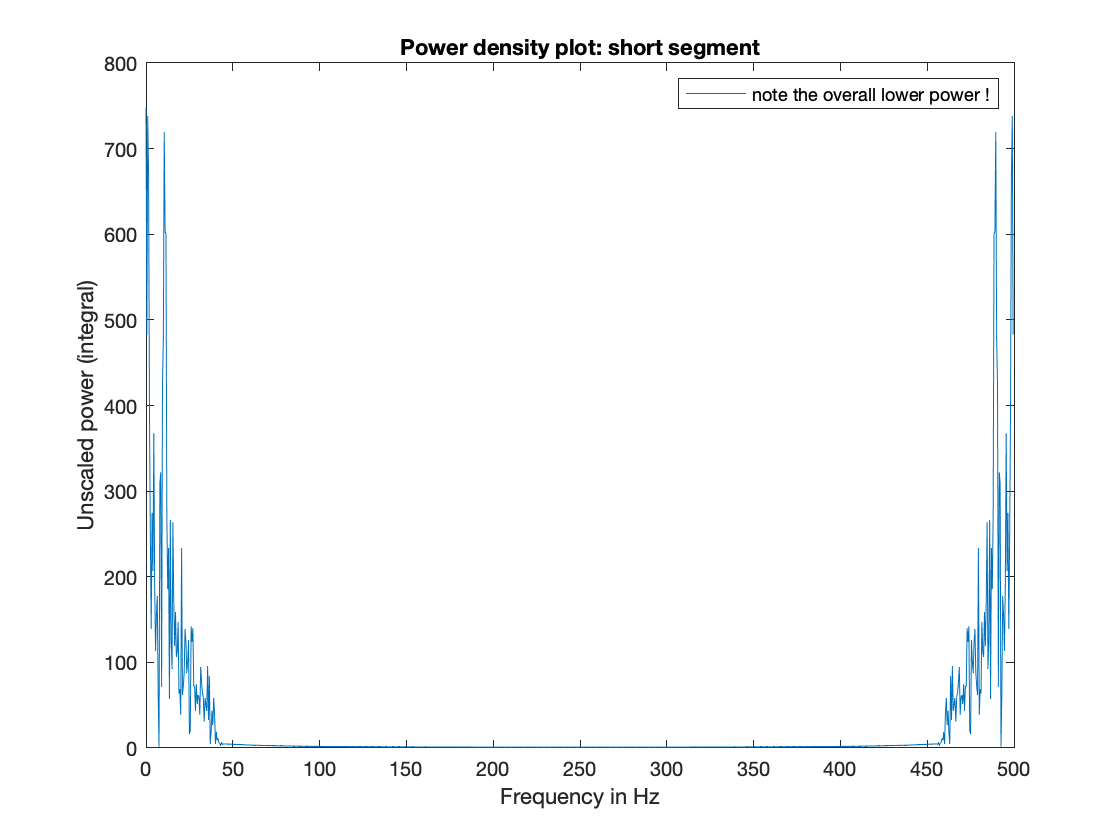

% calculate power with shorter segment
fftMatshort = fft(data(1:1000)); %just 2 seconds of data
magshort = abs(fftMatshort);
freq_axis_short  = 0:1000/(length(data(1:1000))*2):SampRate-0.5;
figure, plot(freq_axis_short, magshort), xlabel('Frequency in Hz'), ylabel('Unscaled power (integral)'), title('Power density plot: short segment'), 
legend('note the overall lower power !')

Now we consider only the part of the spectrum that is valid and scale the power values, so that the true lower half of the spectrum contains all the power in the signal. We do this for the full signal, not the short one above. 

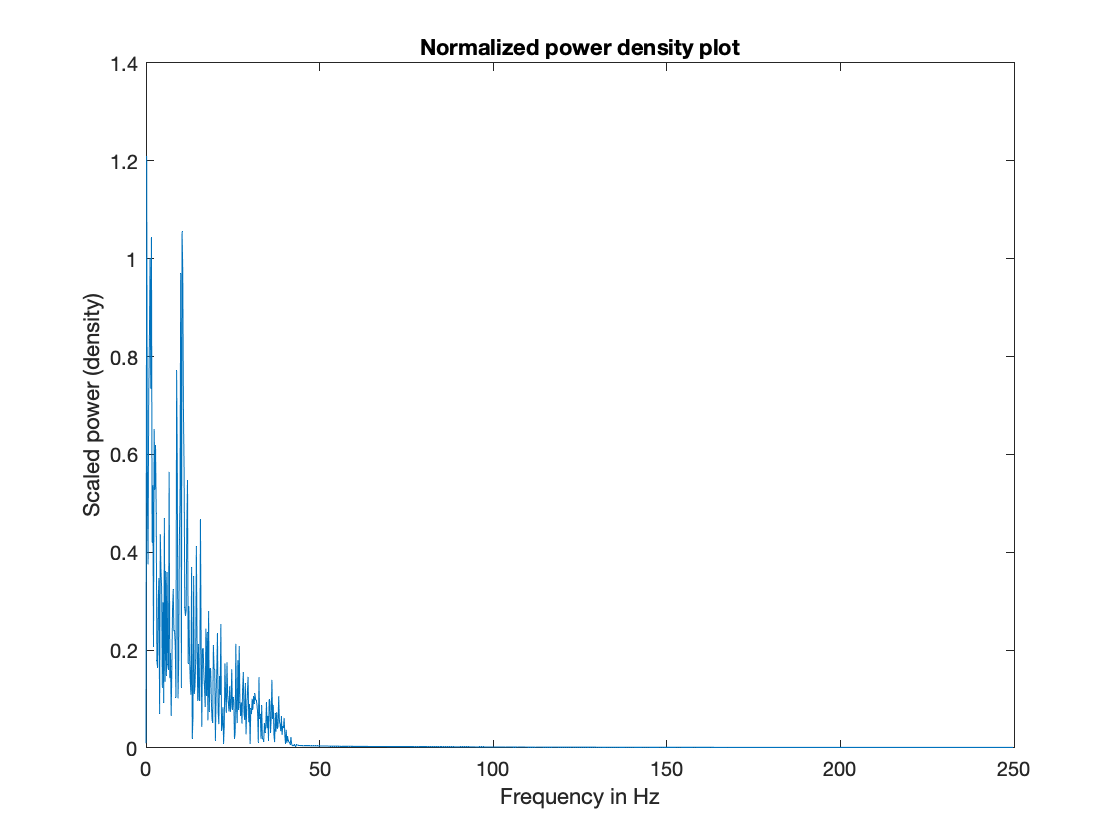

                                                 
Mag = RawMag.*2; % multiply by two, then use only lower half
Mag(1) = Mag(1)/2; % the first value (zero Hz) was not symmetric, so no correction here. 
Mag = Mag/NFFT; % scale by the number of points, so we can compare long and short segments etc
spec = Mag(1:round(NFFT./2)); % take only lower half of the spectrum and plot it
figure, plot(freq_axis(1:1276), spec), xlabel('Frequency in Hz'), ylabel('Scaled power (density)'), title('Normalized power density plot')

Now we have scaled power, but the plot shows irrelevant (filtered) frequency. Let's zoom in 

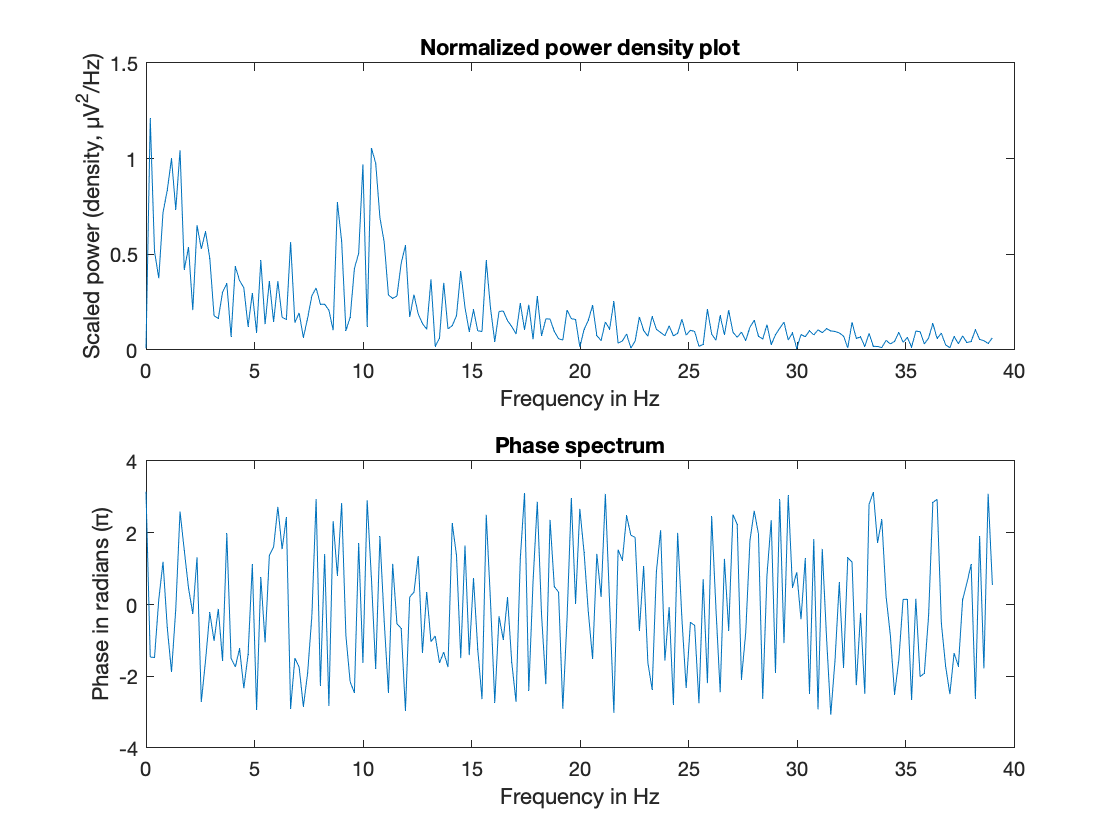

figure, 
subplot(2,1,1), plot(freq_axis(1:200), spec(1:200)), xlabel('Frequency in Hz'), ylabel('Scaled power (density, µV^2/Hz)'), title('Normalized power density plot')
subplot(2,1,2), plot(freq_axis(1:200), Phase(1:200)), xlabel('Frequency in Hz'), ylabel('Phase in radians (π)'), title('Phase spectrum')

### Congrats! this is a valid FFT/DFT. For some applications, this version with no windowing and no averaging within the time segment is best. 

#### Part 2: improving the signal-to noise of the estimate. 

The spectrum on the right is noisy looking and has higher frequency resolution (many x-ticks) than we might want. Instead we woudl like a clear shape and nice signal. In Matlab and most other enviornments, people often use a version of Welch's method, where a window is moved over the signal, DFTs are calculated, and averaged as they are moved. In matlab here is how this works, all in one command: 

 [Pxx,F] = pwelch(X,WINDOW,NOVERLAP,F,Fs)

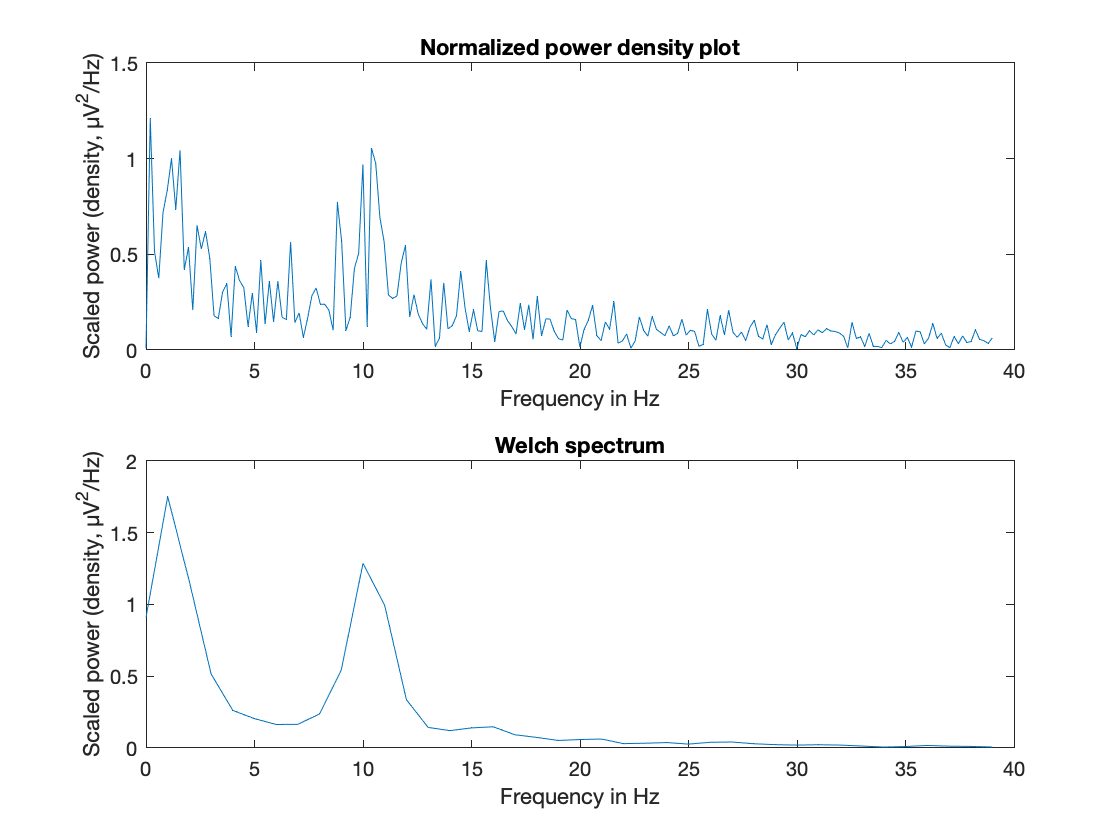

[Pxx,F] = pwelch(data,500,[],500,SampRate); % 50% OOVERLAP is the default
subplot(2,1,1), plot(freq_axis(1:200), spec(1:200)), xlabel('Frequency in Hz'), ylabel('Scaled power (density, µV^2/Hz)'), title('Normalized power density plot')
subplot(2,1,2), plot(F(1:40), Pxx(1:40)), xlabel('Frequency in Hz'), ylabel('Scaled power (density, µV^2/Hz)'), title('Welch spectrum')

Note how the welch spectrum has fewer frequency steps because we used many shorter segments within our data segment, did a spectrum, and averaged the resulting spectra together, to obtain a much smmother, high signal-to-noise version. 

Finally, windows are also sometimes useful, even without averaging, because they minimize/attenuate on and offset artifacts. The sine and cosine functions that the DFT uses as models for the data are infinite and stationary (see slides), thus they create artfifacts at the beginning and end of the signal. 

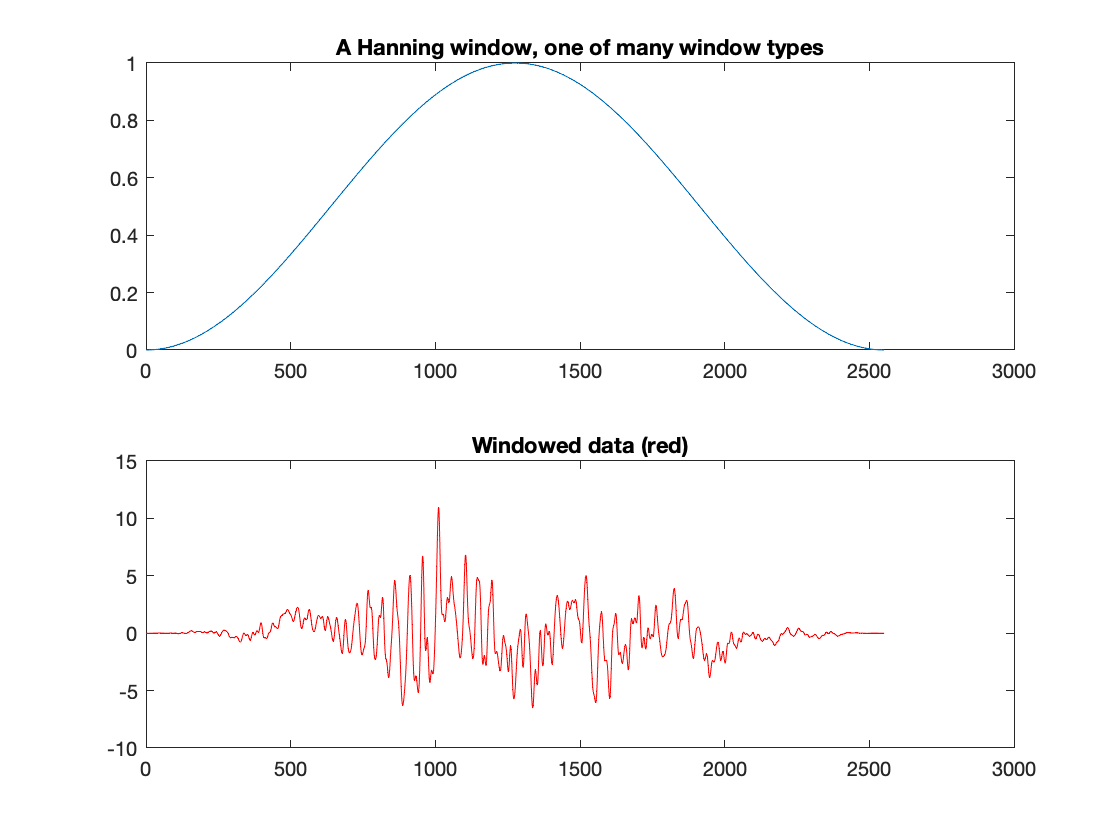

window = hanning(2551); 
figure, 
subplot(2,1,1), plot(window), title ('A Hanning window, one of many window types')
% we multiply this with the data, pointwise
datawindowed = data.* window; 
subplot(2,1,2), plot(datawindowed, 'r'), title ('Windowed data (red)')

compare this with the original data

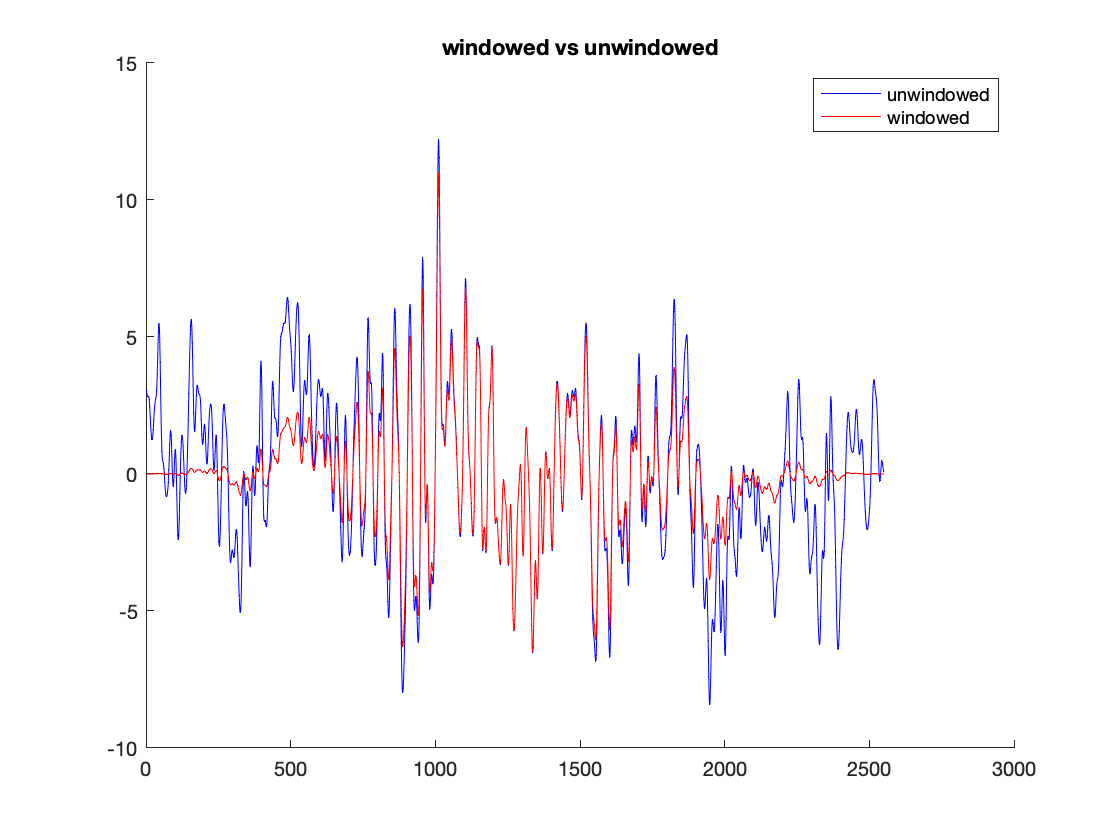


figure,  hold on, plot(data, 'b'), plot(datawindowed, 'r'), title ('windowed vs unwindowed'), legend ('unwindowed', 'windowed')

 Now, we redo the power spectrum for the windowed data. 

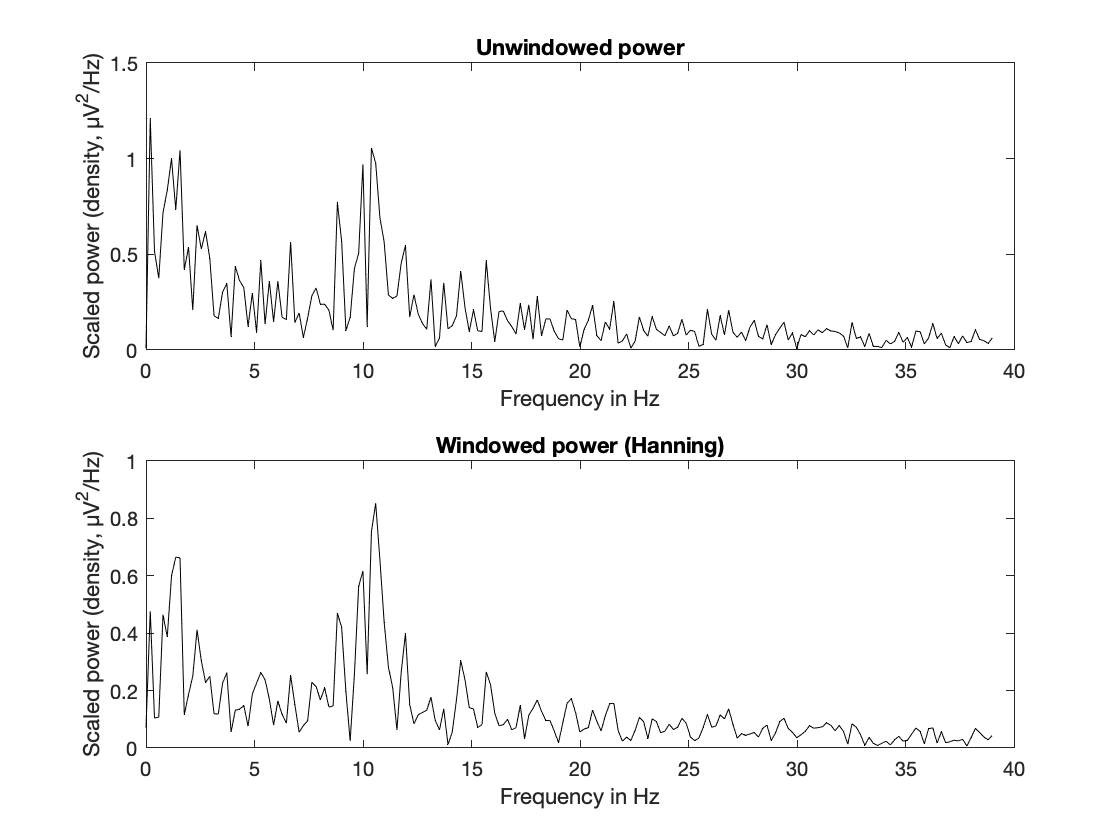

fftwindowed = fft(datawindowed); 
RawMagwindowed = abs(fftwindowed);
Magwindowed = RawMagwindowed.*2; % multiply by two, then use only lower half
MaMagwindowed(1) = Magwindowed(1)/2; % the first value (zero Hz) was not symmetric, so no correction here. 
Magwindowed = Magwindowed/NFFT; % scale by the number of points, so we can compare long and short segments etc
specwindowed = Magwindowed(1:round(NFFT./2)); % take only lower half of the spectrum and plot it

figure, 
subplot(2,1,1), plot(freq_axis(1:200), spec(1:200), 'k'), xlabel('Frequency in Hz'), ylabel('Scaled power (density, µV^2/Hz)'), title('Unwindowed power')
subplot(2,1,2), plot(freq_axis(1:200), specwindowed(1:200), 'k'), xlabel('Frequency in Hz'), ylabel('Scaled power (density, µV^2/Hz)'), title('Windowed power (Hanning)')

Note the smaller value at 0 (zero) Hz in the windowed version, and its overall smoother look. Sometimes windowing is beneficial because of these effects. Also note the overall smaller/lower power in the windowed version. If no window is necessarym this is an undesirabel effect of using unneeded windows. 